# Chapter 3: Taylor's Model

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## 3.1 Taylor's model and equivalent representations

We consider an extension of the linear Abelson model [M2.1](matlab:open('./ch02_abl.mlx')).

Such model involves $n$ agents with opinions $x_1, \dots, x_n \in \mathbb R$ and $m\ge 1$ communication sources, providing static opinions $s_1, \dots, s_m \in \mathbb R$. 

The agents' opinions are influenced by these sources, obeying the model 

                                                        (M3.1)$\dot x_i(t) = \sum^n_{j=1}a_{ij}(x_j(t)-x_i(t))+\sum^m_{k=1}b_{ik}(s_k-x_i(t))$

Such model involves the non-square $n\times m$ nonnegative matrix $B = (b_{ik})$ which describe the influence of the communication sources on the agents:

- $b_{i1}=\dots=b_{im}=0$ agents can be free of the external influence

- $\sum_{k=1}^mb_{ik}>0$ agents are influenced by one or several sources

This model can be considered as the Abelson model with $n+k$ agents, where "virtual" agents $n+1, \dots, n+k$ are stubborn: $x_{n+i}=s_i \text{ for } i = 1, \dots, k$ [**Corollary 2.1**](matlab:open('./ch02_abl.mlx')) imples that the model M3.1 is **convergent**: for any $x(0) \text{ and } s_1, \dots, s_k$ there exist the limit $x(\infty) = \lim_{t\rightarrow \infty}x(t)$. 

The converse is also true: for the Abelson model with $k\ge1$ stubborn agents, their static opinions may be considered as "communication sources" for the others.

Another transofrmation allows to reduce M3.1 to a formally less general model, where each agent may have its own "communicstion source" or **prejudice**

                                                                (M3.2)$\dot x_i(t) = \sum^n_{j=1}a_{ij}(x_j(t)-x_i(t))+\gamma_i(u_i-x_i(t))$

where $\gamma_i\ge0$. 

By choosing $\gamma_i \triangleq \sum_{m=1}^k b_{im}\ge0$ and $u_i \triangleq \gamma_i^{-1}\sum_{m=1}^kb_{im}s_m$ (if $\gamma_i=0$ we set $u_i=0$ w.l.o.g.)  M3.1 reduces to M3.2.

Given a group of $n$ agents, governed by the model M3.2, we call an agent $i$ **prejudiced **if $\gamma_i>0$; the extrnal inputs $u_i$ are referred to as the **prejudices **of corresponding agents.

An agent that is not prejudiced obeys the usual Abelson mechanism [M2.1](matlab:open('./ch02_abl.mlx')).

A prejudiced agent may be totally closed to the interpersonal influence $a_{ij}=0\forall j$; in this case its opinion converges to its prejudice $x_i(t)\rightarrow u_i \text{ for } t \rightarrow \infty$ and $\gamma_i$ regulates the convergence rate.

In the special case where $u_i = x_i(0)$ such an agent is stubborn since $x_i(t) \equiv u_i$.

## 3.2 Stability of the Taylor model

It is sufficient to study M3.2 since it can reduce to M3.1.

By introducing the matrix $\Gamma = diag(\gamma_1, \dots, \gamma_n)$ the model M3.2 is rewritten as

                                                                        (M3.3)$\dot x(t) = -(L[A]+\Gamma)x(t)+\Gamma u$

We split agents in two classes:

- Agent $i$ is said to be **P-dependent **(prejudice dependent, for simplicity **PD**) if is either prejudiced or influenced by some prejudiced agent $j$ (ie: a walk from $j$ to $i$ exists in the graph $\mathcal G [A]$).

- Agent i is said to be **P-independent **(for simplicity **PI**) otherwise.

Assume agents $1, \dots,r\ge 1$ are PD and agents $r+1,\dots,n$ are PI (possibly $r=n$). Denote the corresponding parts of the opinion vecotr by, respectively, $x^1(t)$ and $x^2(t)$. 

Since PD agents are not conntected to PI ones M3.3 is decomposed as

                                                            (M3.3.1)$\dot x^1(t) = -(L^{11}+\Gamma^{11})x^1(t)-L^{12}x^2(t)+\Gamma^{11}u^1$

                                                                                (M3.3.2)$\dot x^2(t) = -L^{22}x^2(t)$

The matrix $L^{22}$ is Laplacian of size $(n-r)\times(n-r)$, ie M3.3.2 is the Abelson model. The matrix $L^{11}$ is, in general, not Laplacian; one has $L^{11}\mathbb 1_r \ge 0$

**Theorem 3.1 **Let the community have $r \ge 1$ PD agents and $n-r \ge 0$ PI ones. Then the dynamics of PD agents M3.3.1 is asymptotically stable, ie the matrix $-(L^{11}+\Gamma^{11})$ is Hurwitz. The vetor of their opinions converges to

                                                                                
$$x^1(\infty) = M [u^1 , x^2(\infty)]^T \\
M \triangleq (L^{11}+\Gamma^{11})^{-1}[\Gamma^{11} \ L^{12}]$$


The matrix M is stochastic, and thus the final opinion of any agent is a convex combination of the prjudices and the final opinions of PI agents

**Corollary 3.1 **The system M3.3 is asymptotically stable, ie $-(L[A]+\Gamma)$ is Hurwit $\iff$ all agents are PD.

The corollary can be reformulated as follows: the system M3.3 is asymptotically stable $\iff$ any agent is influenced by at least one "communication source". 

This influence can be:

- **Direct influence **$\gamma_i = \sum^k_{m=1}b_{im}>0$.

- **Indirect influence **through a chain of the other agents.

## 3.3 The Taylor model and containment control

A multidimensional extension of the M3.1 arises in the containment control problems. The agents stand for mobile robots and the opinion $x_i \in \mathbb R^d$ is the position of agent $i$. Similar to scalar case, such agents can be called "prejudiced". The communication sources $s_1, \dots, s_k \in \mathbb R^d$ are the positions of $k$ static leaders.

The mobile agents' coal is to reach the convex hull

                                                                        
$$\mathcal S \triangleq \left\{ \sum_{m = 1}^k \alpha_ms_m:\alpha_m\ge 0, \sum_{m = 1}^k \alpha_m = 1 \right\}\subset \mathbb R^d$$


spanned by the leaders $s_1, \dots, s_k$. Agent $i$ is indirectly influenced by the leader $m$ (ie. $b_{im}>0$) if it can measure its position (in general, none of the agents can observe the whole set $\mathcal S$). Similar to scalar case, such agents can be call "prejudiced".The other agents can be either PD or PI.

**Theorem 3.2 **The three conditions are equivalent:

- The system M3.3 is Hurwitz stable

- Any agent is influenced directly or indirectly by one of the leaders (PD)

- The mobile agents reach the target convex hull $x_i(\infty) \in \mathcal S \ \forall i = 1,\dots, n$ for any position of the leaders $s_1, \dots, s_k \in \mathbb R^d$ and the initia conditions $x_1(0), \dots, x_n(0)\in \mathbb R^d$

Such theorem has been extended in various directions: the leaders may be dynamic (ie: convex hull is time varying $\mathcal S = \mathcal S(t)$), the interaction grpah may also be time-varying and the agents may have non-trivial dynamics. Furthermore, the polyhedron $\mathcal S$ can be replaced by an arbitrary closed convex set; the relevant problem is sometimes referred to as the *target aggregation* and is closely related to distributed optimization.

## 3.4 Examples

The model is simulated exactly: the affine flow is propagated by one matrix exponential, so no step size or solver tolerance enters. Every example states which theoretical result it is checking.

N  = 6;
x0 = [3; -1; 5; 0; 2; -2];
t  = linspace(0, 20, 500);

fprintf('N = %d agents\n', N);

N = 6 agents


## 3.4.1 The two equivalent representations

Section 3.1 gives two ways of rewriting M3.1. It is an Abelson model on n + m agents in which the m sources are stubborn virtual agents, and it reduces to M3.2 with one prejudice per agent, gamma_i = sum_k b_ik and u_i = gamma_i^{-1} sum_k b_ik s_k. Both are checked against the same trajectory.

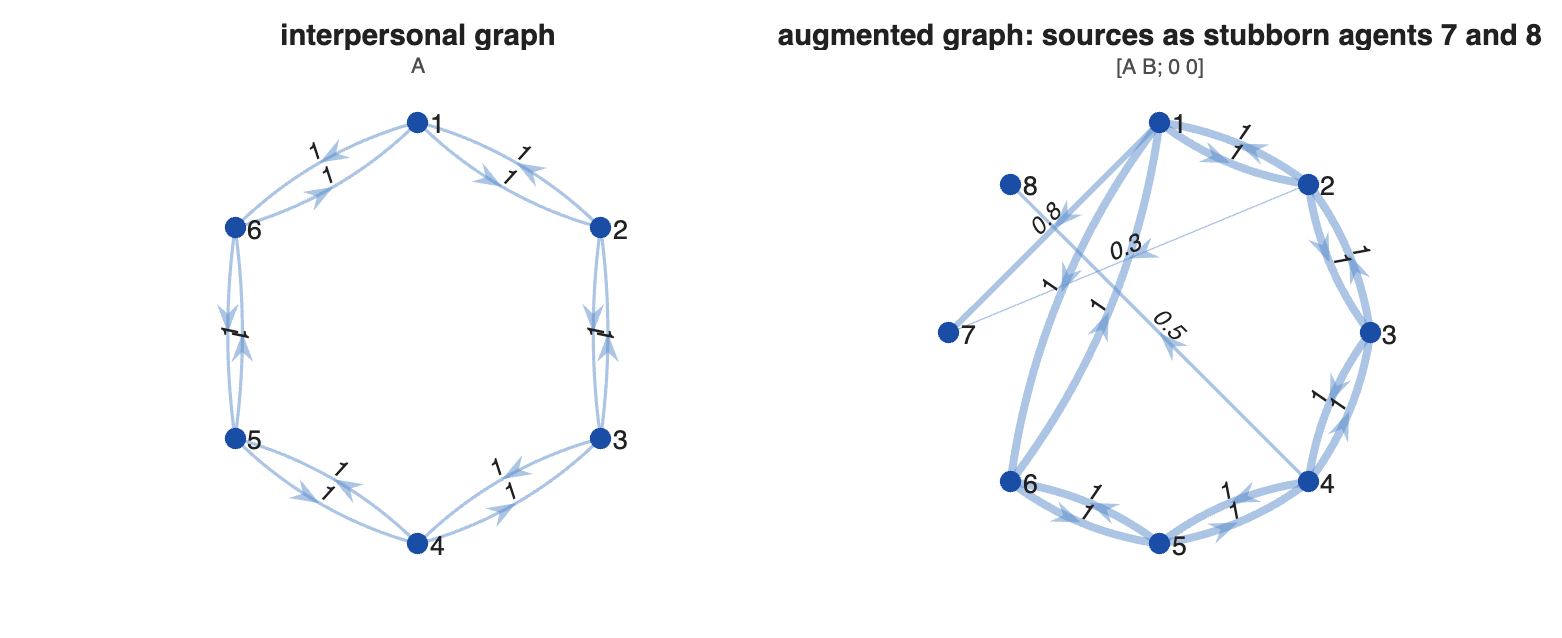

A = ring_graph(N) + ring_graph(N).';       % interpersonal influence
B = zeros(N,2);
B(1,1) = 0.8;  B(2,1) = 0.3;  B(4,2) = 0.5;   % who senses which source
sSrc = [-2; 4];                                % the two static sources

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile; plot_graph(A, [], 'Title','interpersonal graph', 'Subtitle','A');
nexttile; plot_graph([A B; zeros(2, N+2)], [], ...
    'Title','augmented graph: sources as stubborn agents 7 and 8', 'Subtitle','[A B; 0 0]');


B

B =     0.8000         0
    0.3000         0
         0         0
         0    0.5000
         0         0
         0         0


sSrc

sSrc =     -2
     4


% reduction M3.1 -> M3.2
gamma = sum(B, 2);
u     = zeros(N,1);
anch  = gamma > 0;
u(anch) = (B(anch,:) * sSrc) ./ gamma(anch);

disp(table((1:N).', gamma, u, anch, 'VariableNames', {'agent','gamma','u','prejudiced'}))

    agent    gamma    u     prejudiced
    _____    _____    __    __________

      1       0.8     -2      true    
      2       0.3     -2      true    
      3         0      0      false   
      4       0.5      4      true    
      5         0      0      false   
      6         0      0      false   




Xtay = sim_taylor(A, gamma, u, x0, t);                       % M3.2
Xabl = sim_abelson([A B; zeros(2, N+2)], [x0; sSrc], t);      % M3.1 as Abelson

fprintf('max |M3.2 trajectory - augmented Abelson trajectory| = %.3e\n', ...
    max(max(abs(Xtay - Xabl(1:N,:)))));

max |M3.2 trajectory - augmented Abelson trajectory| = 2.220e-15


fprintf('the two virtual agents moved by                        %.3e\n', ...
    max(max(abs(Xabl(N+1:end,:) - sSrc))));

the two virtual agents moved by                        0.000e+00


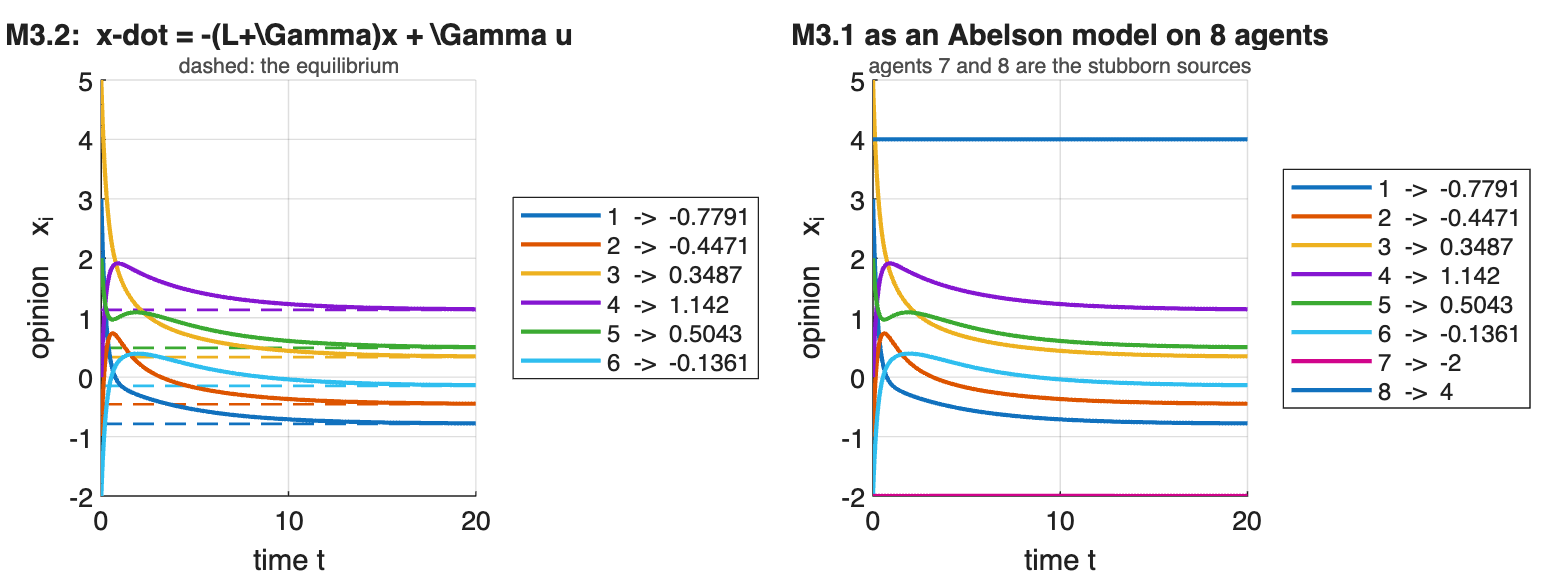

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile;
plot_opinions(Xtay, t, 'Limit', taylor_equilibrium(A, gamma, u), ...
    'Title','M3.2:  x-dot = -(L+\Gamma)x + \Gamma u', 'Subtitle','dashed: the equilibrium');
nexttile;
plot_opinions(Xabl, t, 'Title','M3.1 as an Abelson model on 8 agents', ...
    'Subtitle','agents 7 and 8 are the stubborn sources');

The two runs coincide to rounding error, so the reduction and the Abelson embedding are the same system written three ways. The embedding also explains why the Taylor model converges at all: it inherits Corollary 2.1 from the previous chapter.

## 3.4.2 What the prejudice adds

Setting gamma = alpha * gamma_0 and turning alpha interpolates between the two models. At alpha = 0 the system is exactly Abelson; as alpha grows each prejudiced agent is pulled harder towards its own u_i.

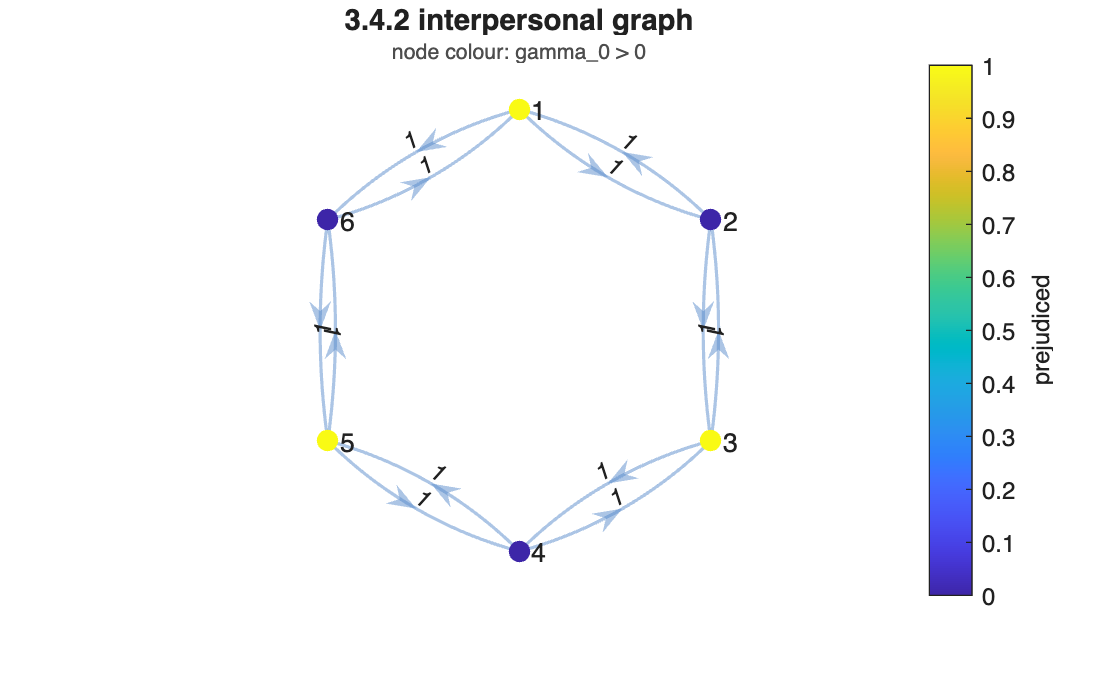

A  = ring_graph(N) + ring_graph(N).';
g0 = [1; 0; 1; 0; 1; 0];              % agents 1, 3, 5 are prejudiced
u  = [-4; 0; 0; 0; 4; 0];

figure;
plot_graph(A, [], 'NodeValue', g0, 'NodeName','prejudiced', ...
    'Title','3.4.2 interpersonal graph', 'Subtitle','node colour: gamma_0 > 0')

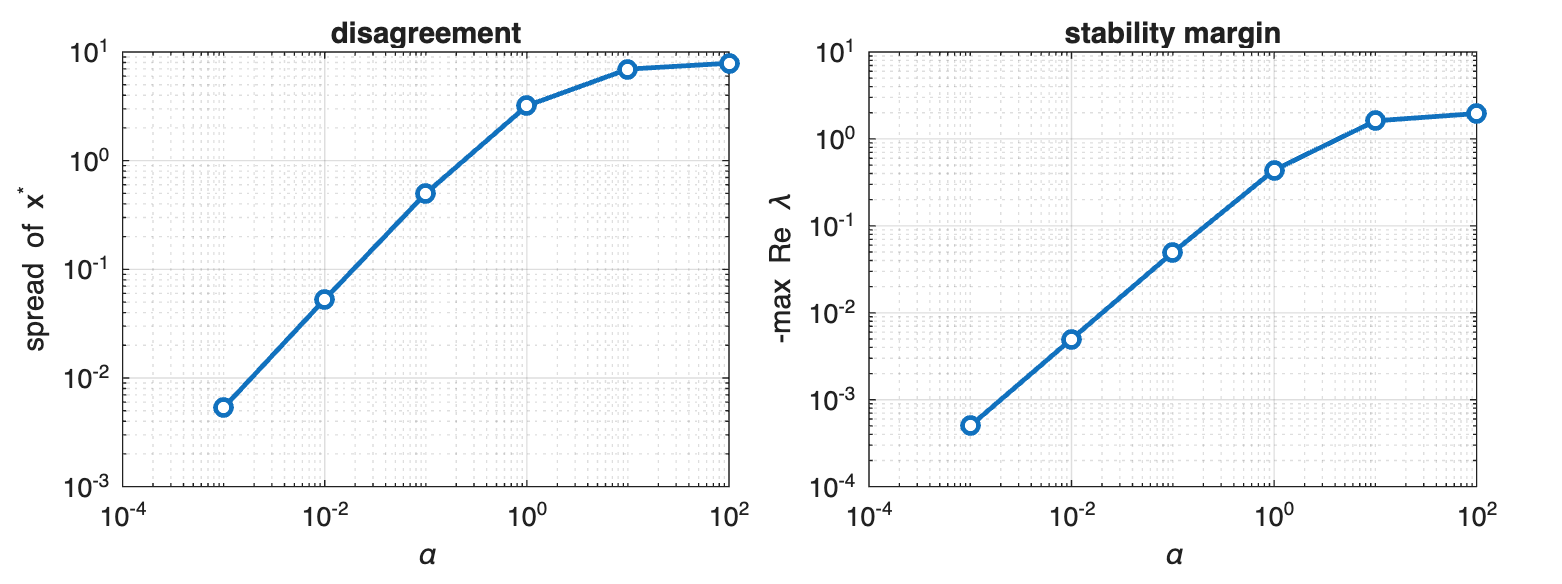


alphas = [1e-3 1e-2 1e-1 1 10 100];
spread = zeros(size(alphas));
maxRe  = zeros(size(alphas));
for k = 1:numel(alphas)
    g  = alphas(k) * g0;
    xs = taylor_equilibrium(A, g, u);
    spread(k) = max(xs) - min(xs);
    maxRe(k)  = max(real(eig(-(laplacian(A) + diag(g)))));
end

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
nexttile; loglog(alphas, spread, 'o-', 'LineWidth',1.8, 'MarkerFaceColor','w'); grid on
xlabel('\alpha'); ylabel('spread of x^*'); title('disagreement', 'FontWeight','bold');
nexttile; loglog(alphas, -maxRe, 'o-', 'LineWidth',1.8, 'MarkerFaceColor','w'); grid on
xlabel('\alpha'); ylabel('-max Re \lambda'); title('stability margin', 'FontWeight','bold');

The two panels move together: stronger anchoring buys stability and costs agreement. The spectrum says the same thing, with the eigenvalue that sits at the origin under Abelson pushed into the left half-plane as soon as alpha > 0.

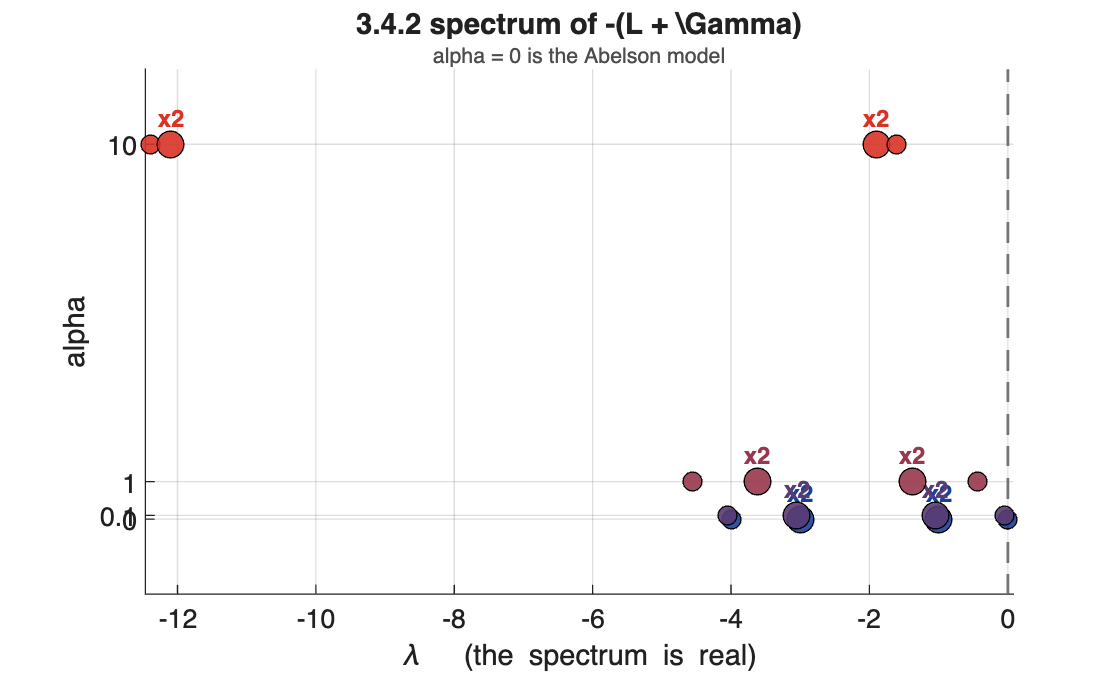

Ms = arrayfun(@(a) -(laplacian(A) + diag(a*g0)), [0 0.1 1 10], 'UniformOutput', false);

figure;
plot_spectrum_family(Ms, [0 0.1 1 10], 'continuous', 'Label','alpha', ...
    'Title','3.4.2 spectrum of -(L + \Gamma)', 'Subtitle','alpha = 0 is the Abelson model');

One consequence deserves a direct check. For every alpha > 0 the equilibrium is unique and does not depend on x(0); at alpha = 0 exactly, the Abelson limit is px(0) and does depend on it. Arbitrarily weak anchoring already erases the initial condition, it merely takes a long time to do so.

fprintf('Abelson limit  (alpha = 0)      : %+.4f   (depends on x(0))\n', ...
    laplacian_power(A).' * x0);

Abelson limit  (alpha = 0)      : +1.1667   (depends on x(0))


fprintf('weighted average of prejudices  : %+.4f\n', ...
    (laplacian_power(A).' * (g0.*u)) / (laplacian_power(A).' * g0));

weighted average of prejudices  : -0.0000


for a = [1e-3 1e-2 1e-1]
    xs = taylor_equilibrium(A, a*g0, u);
    fprintf('Taylor equilibrium, alpha = %-6g: mean %+.4f, spread %.4f\n', ...
        a, mean(xs), max(xs)-min(xs));
end

Taylor equilibrium, alpha = 0.001 : mean +0.0000, spread 0.0053
Taylor equilibrium, alpha = 0.01  : mean -0.0000, spread 0.0530
Taylor equilibrium, alpha = 0.1   : mean +0.0000, spread 0.5000


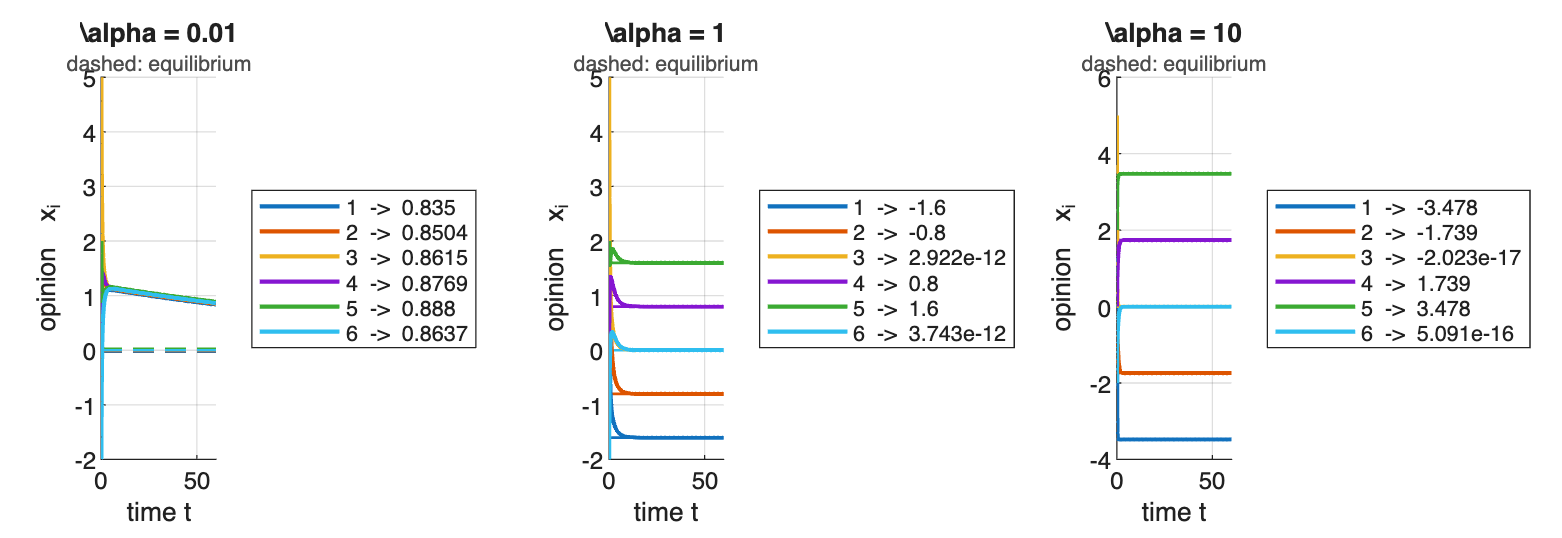


figure('Position',[0 0 1250 430]);
tiledlayout(1, 3, 'TileSpacing','compact', 'Padding','compact');
for a = [0.01 1 10]
    nexttile;
    X = sim_taylor(A, a*g0, u, x0, linspace(0, 60, 600));
    plot_opinions(X, linspace(0,60,600), 'Limit', taylor_equilibrium(A, a*g0, u), ...
        'Title', sprintf('\\alpha = %g', a), 'Subtitle','dashed: equilibrium');
end

## 3.4.3 P-dependence, stability and the limit

Corollary 3.1 makes stability a reachability property: the system is asymptotically stable exactly when every agent is reached by some source, directly or along a chain. The two graphs below differ only in whether that holds.

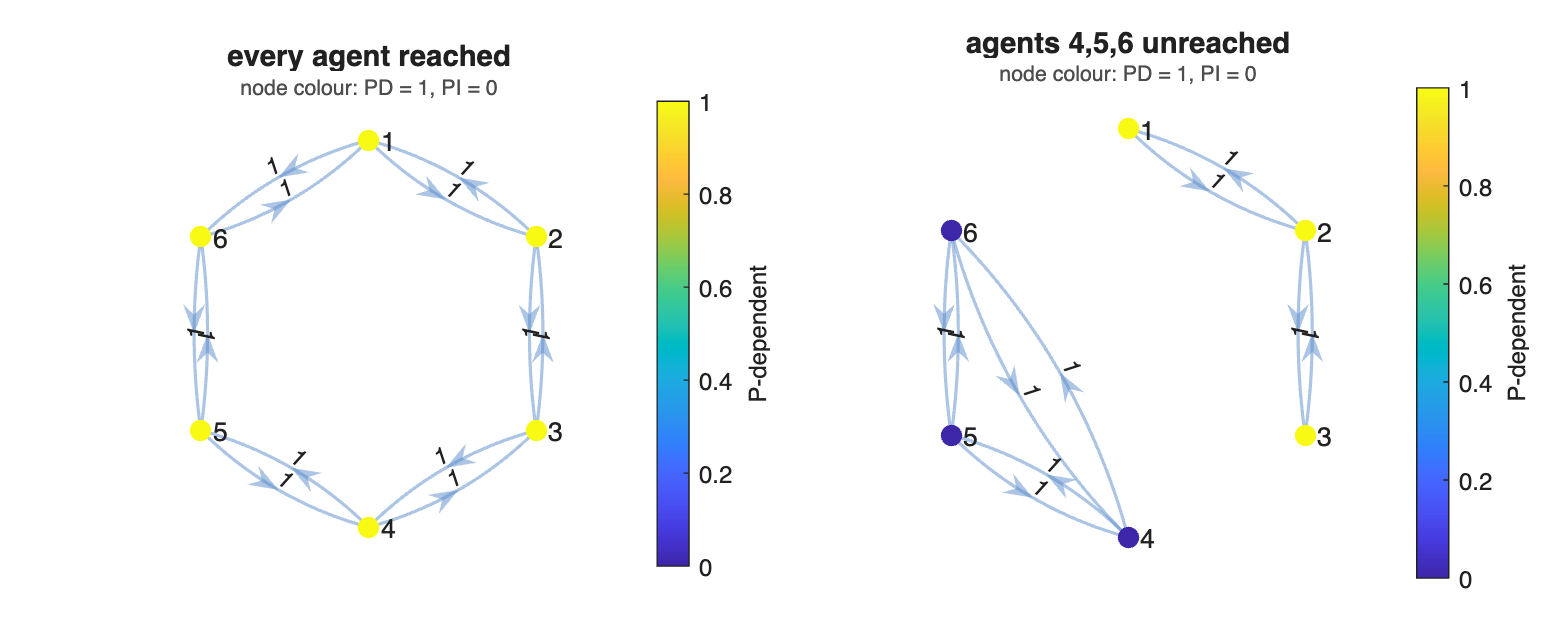

% (a) every agent reached;  (b) agents 4,5,6 cut off from the prejudiced agent
Aa = zeros(N); ea = [1 2;2 3;3 4;4 5;5 6;6 1];
for e = ea.', Aa(e(1),e(2)) = 1; Aa(e(2),e(1)) = 1; end

Ab = zeros(N); eb = [1 2;2 3;4 5;5 6;6 4];
for e = eb.', Ab(e(1),e(2)) = 1; Ab(e(2),e(1)) = 1; end

gc = [0; 0; 1; 0; 0; 0];      % only agent 3 is prejudiced
uc = [0; 0; 7; 0; 0; 0];

cases = {'every agent reached', Aa; 'agents 4,5,6 unreached', Ab};

figure('Position',[0 0 1150 470]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    pd = prejudice_reach(cases{k,2}, gc > 0);
    nexttile;
    plot_graph(cases{k,2}, [], 'NodeValue', double(pd), 'NodeName','P-dependent', ...
        'Title', cases{k,1}, 'Subtitle','node colour: PD = 1, PI = 0');
end


for k = 1:2
    pd = prejudice_reach(cases{k,2}, gc > 0);
    ev = eig(-(laplacian(cases{k,2}) + diag(gc)));
    fprintf('%-24s PD = %-10s  max Re = %+.4f   Hurwitz = %d\n', cases{k,1}, ...
        mat2str(find(pd).'), max(real(ev)), max(real(ev)) < -1e-9);
end

every agent reached      PD = [1 2 3 4 5 6]  max Re = -0.1088   Hurwitz = 1
agents 4,5,6 unreached   PD = [1 2 3]     max Re = +0.0000   Hurwitz = 0


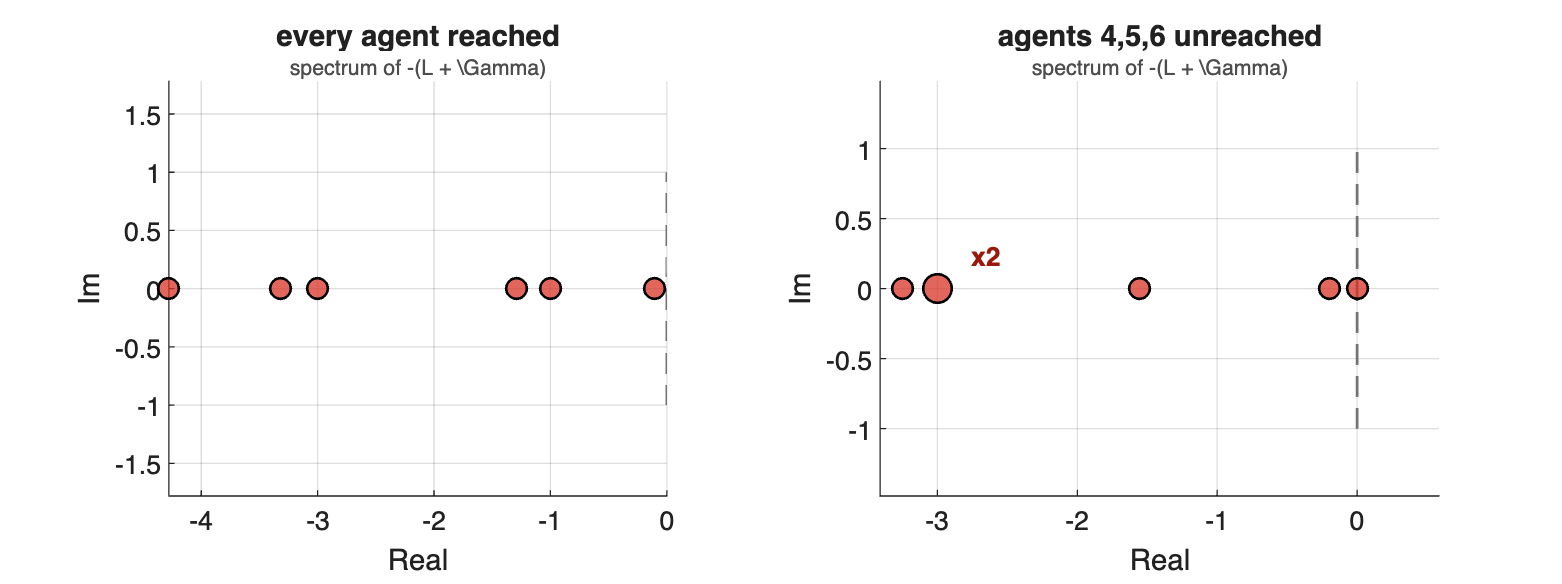

figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    plot_eigenvalues(-(laplacian(cases{k,2}) + diag(gc)), 'continuous', ...
        'Title', cases{k,1}, 'Subtitle','spectrum of -(L + \Gamma)');
end

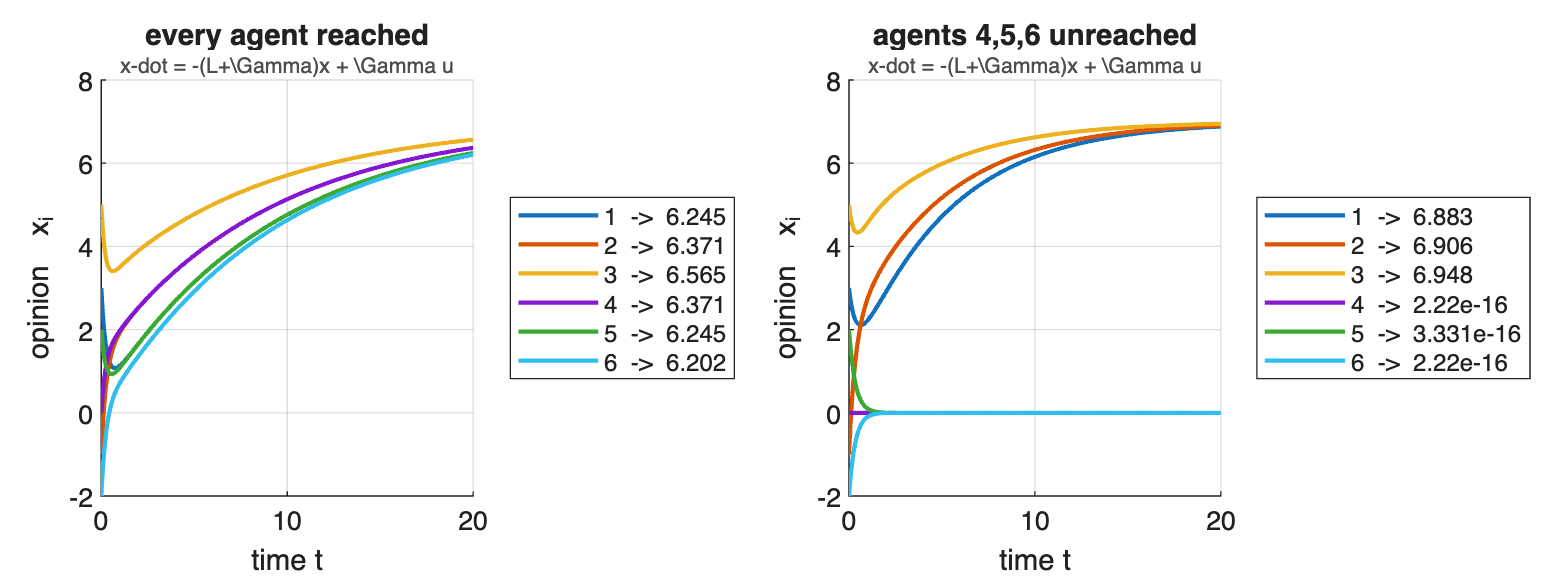


figure('Position',[0 0 1150 430]);
tiledlayout(1, 2, 'TileSpacing','compact', 'Padding','compact');
for k = 1:2
    nexttile;
    X = sim_taylor(cases{k,2}, gc, uc, x0, t);
    plot_opinions(X, t, 'Title', cases{k,1}, 'Subtitle','x-dot = -(L+\Gamma)x + \Gamma u');
end

In the first graph L + Gamma is Hurwitz and every agent converges to the single prejudice. In the second the unreached agents keep an eigenvalue at the origin: they run the pure Abelson model among themselves and settle at their own consensus, which the prejudice never touches.

Theorem 3.1 describes that limit exactly. Splitting the state into the P-dependent and P-independent blocks, the PD opinions converge to M [u1; x2(inf)] with M stochastic, so every final opinion is a convex combination of the prejudices and the PI limits.

Ai = cases{2,2};
pd = prejudice_reach(Ai, gc > 0);
p1 = find(pd).';   p2 = find(~pd).';

L  = laplacian(Ai);   G = diag(gc);
M  = (L(p1,p1) + G(p1,p1)) \ [G(p1,p1), -L(p1,p2)];

fprintf('M is %d-by-%d\n', size(M,1), size(M,2));

M is 3-by-6


fprintf('row sums  : %s\n', mat2str(round(sum(M,2).', 10)));

row sums  : [1 1 1]


fprintf('min entry : %.3e   -> stochastic\n', min(M(:)));

min entry : 0.000e+00   -> stochastic



X = sim_taylor(Ai, gc, uc, x0, linspace(0, 200, 400));
fprintf('predicted x1(inf) : %s\n', mat2str(round((M * [uc(p1); X(p2,end)]).', 4)));

predicted x1(inf) : [7 7 7]


fprintf('simulated  x1(inf) : %s\n', mat2str(round(X(p1,end).', 4)));

simulated  x1(inf) : [7 7 7]


## 3.4.4 Containment control

Theorem 3.2 states three equivalent conditions, and the third is geometric: the agents reach the convex hull of the leaders for any leader positions and any initial conditions, exactly when every agent is P-dependent. Positions are planar, and each coordinate obeys the same scalar model, so the two coordinates are simulated separately.

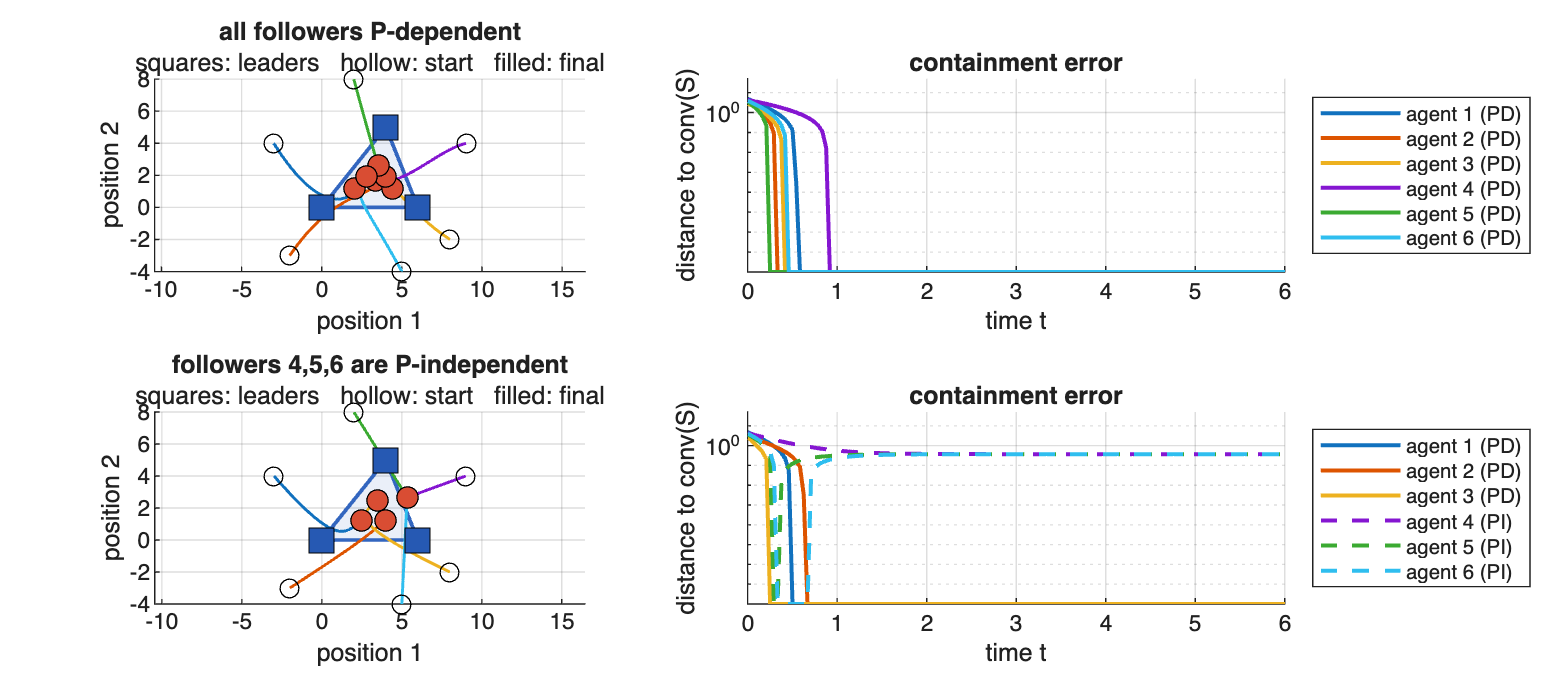

all followers P-dependent            PD = [1 2 3 4 5 6]   agents inside at t = 25 : 6 / 6
followers 4,5,6 are P-independent    PD = [1 2 3]         agents inside at t = 25 : 3 / 6


S  = [0 0; 6 0; 4 5];                          % three static leaders
X0 = [-3 4; -2 -3; 8 -2; 9 4; 2 8; 5 -4];      % initial follower positions

% (a) all followers P-dependent   (b) followers 4,5,6 sense nothing
Ac = zeros(N); ec = [1 2;2 3;3 4;4 5;5 6;6 1;2 5];
for e = ec.', Ac(e(1),e(2)) = 1; Ac(e(2),e(1)) = 1; end
Bc = zeros(N,3); Bc(1,1) = 1; Bc(3,2) = 1; Bc(5,3) = 1;

Ad = zeros(N); ed = [1 2;2 3;3 1;4 5;5 6;6 4];
for e = ed.', Ad(e(1),e(2)) = 1; Ad(e(2),e(1)) = 1; end
Bd = zeros(N,3); Bd(1,1) = 1; Bd(2,2) = 1; Bd(3,3) = 1;

runs = {'all followers P-dependent', Ac, Bc; 'followers 4,5,6 are P-independent', Ad, Bd};
tc   = linspace(0, 25, 600);
figure('Position',[0 0 1250 540]);
tiledlayout(2, 2, 'TileSpacing','compact', 'Padding','compact');
hull = convhull(S(:,1), S(:,2));

for k = 1:2
    Ak = runs{k,2};  Bk = runs{k,3};
    g  = sum(Bk, 2);
    U  = zeros(N,2);  nz = g > 0;
    U(nz,:) = (Bk(nz,:) * S) ./ g(nz);
    pd = prejudice_reach(Ak, g > 0);

    P = zeros(N, numel(tc), 2);
    for c = 1:2, P(:,:,c) = sim_taylor(Ak, g, U(:,c), X0(:,c), tc); end

    % --- the plane -----------------------------------------------------
    nexttile; hold on
    fill(S(hull,1), S(hull,2), [0.20 0.40 0.75], 'FaceAlpha', 0.10, ...
         'EdgeColor', [0.20 0.40 0.75], 'LineWidth', 1.4);
    plot(P(:,:,1).', P(:,:,2).', 'LineWidth', 1.1);
    plot(X0(:,1), X0(:,2), 'ko', 'MarkerSize', 7);
    plot(P(:,end,1), P(:,end,2), 'ko', 'MarkerFaceColor', [0.85 0.30 0.20], 'MarkerSize', 8);
    plot(S(:,1), S(:,2), 'ks', 'MarkerFaceColor', [0.15 0.35 0.70], 'MarkerSize', 12);
    axis equal; grid on; xlabel('position 1'); ylabel('position 2');
    title(runs{k,1}, 'FontWeight','bold');
    subtitle('squares: leaders   hollow: start   filled: final');

    % --- distance to the hull ------------------------------------------
    dist = zeros(N, numel(tc));
    for j = 1:numel(tc)
        dist(:,j) = containment_distance([P(:,j,1), P(:,j,2)], S);
    end
    tag = {'PI','PD'};
    nexttile; hold on
    for i = 1:N
        if pd(i), st = '-'; else, st = '--'; end
        plot(tc, max(dist(i,:), 1e-8), st, 'LineWidth', 1.5, ...
             'DisplayName', sprintf('agent %d (%s)', i, tag{1 + pd(i)}));
    end
    set(gca,'YScale','log'); grid on; legend('Location','eastoutside');
    xlabel('time t'); ylabel('distance to conv(S)');
    ylim([1e-8 50]); xlim([0 6]);          % the floor must sit inside ylim,
    title('containment error', 'FontWeight','bold');   % or the curves are clipped

    fprintf('%-36s PD = %-14s  agents inside at t = %g : %d / %d\n', runs{k,1}, ...
        mat2str(find(pd).'), tc(end), nnz(dist(:,end) < 1e-6), N);
end

In the first run every agent is P-dependent, L + Gamma is Hurwitz and all six containment errors fall to zero: the followers enter the triangle and stay there. In the second the three unreached agents never approach it, and their distance flattens at a positive value. That is condition (2) of Theorem 3.2 failing, and conditions (1) and (3) failing with it.